## Gabriel Werpel Fernandes

## June 2024

## Load Data

% Close all figures and clear variables
clc;
close all;
clearvars;

%Process EEG Data
data = processAllEEGData();

Data for file A1_Full_Block.bdf processed successfully
Data for file A3_Full_Block.bdf processed successfully
Data for file A4_Full_Block.bdf processed successfully
Data for file A6_Alpha.bdf processed successfully
Data for file A8_Alpha.bdf processed successfully
Data for file A9_Alpha.bdf processed successfully
Data for file C12_Alpha.bdf processed successfully
Data for file C13_Alpha.bdf processed successfully
Data for file C15_Alpha.bdf processed successfully
Data for file C1_Alpha.bdf processed successfully


## Plot Time-Series

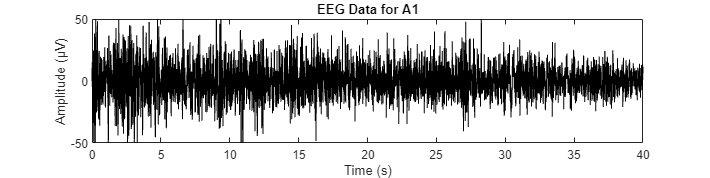

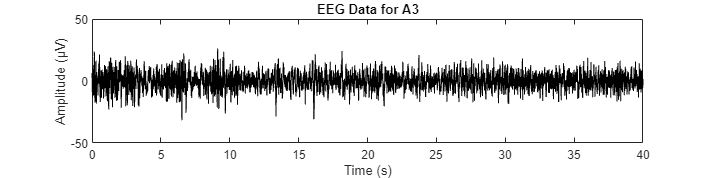

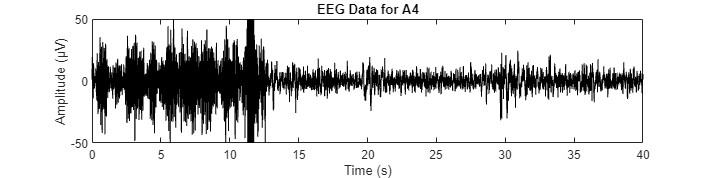

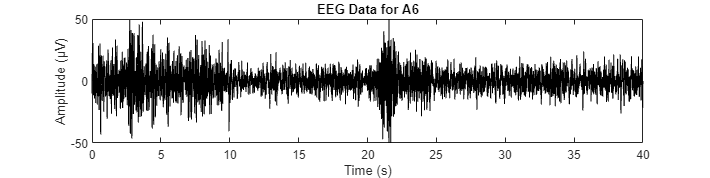

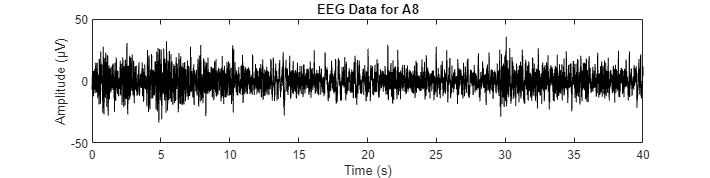

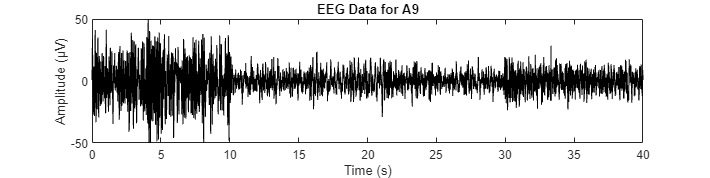

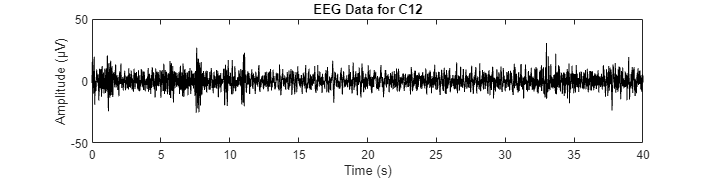

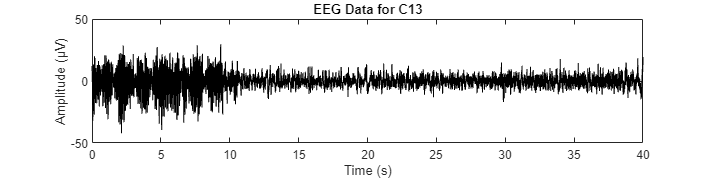

% Plot all EEG data
plotAllEEGData(data);

## Segment Data

% Segment the EEG data
segmentedData = segmentEEGDataNew1s(data);

## Time-Domain Analysis

### Statistical Measures: Mean, Variance, Std. Deviation, Skewness and Kurtosis

% Calculate and display the extended statistics for all keys and sections
extendedStatisticsResults = calculateExtendedStatisticsForAllSections(segmentedData);

      Key             Section             DataType      Mean     Variance    StandardDeviation    Skewness    Kurtosis
    _______    ______________________    __________    ______    ________    _________________    ________    ________

    {'A1' }    {'EC'                }    {'Normal'}    -0.158     320.02           17.889           0.012       3.441 
    {'A1' }    {'EO'                }    {'Normal'}     0.091     132.71            11.52           0.158       3.535 
    {'A1' }    {'DEC'               }    {'Normal'}    -0.053     110.51           10.512           0.291       3.935 
    {'A1' }    {'NDEC'              }    {'Normal'}    -0.005     72.832            8.534           0.066       3.082 
    {'A1' }  

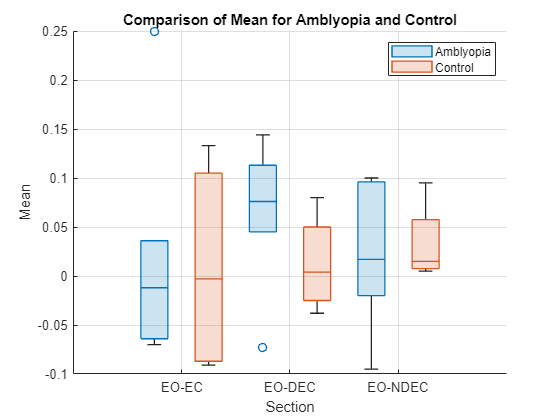

% Load the data
data = readtable('TableA.1.1.csv');

% Call the function for each metric
plotBoxChart(data, 'Mean', 'Mean');

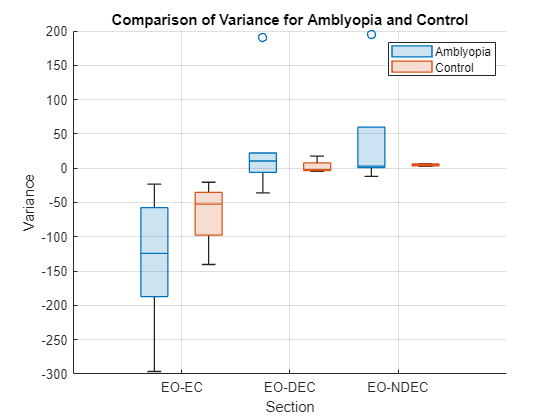

plotBoxChart(data, 'Variance', 'Variance');

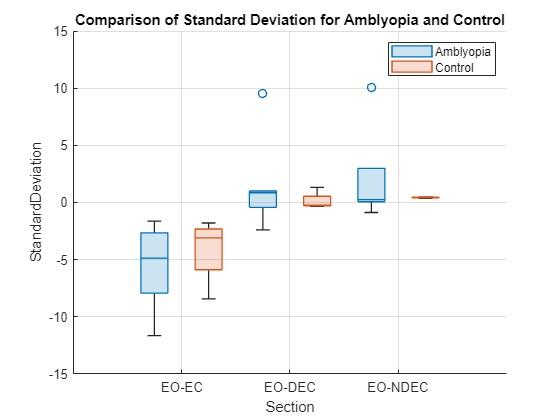

plotBoxChart(data, 'StandardDeviation', 'Standard Deviation');

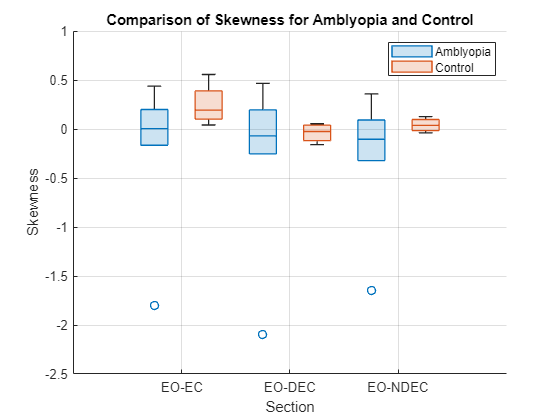

plotBoxChart(data, 'Skewness', 'Skewness');

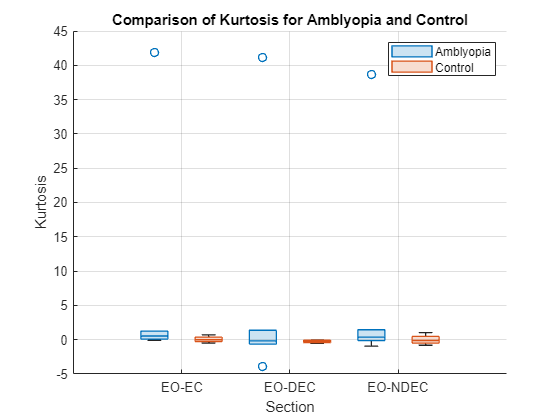

plotBoxChart(data, 'Kurtosis', 'Kurtosis');

calculateStatisticalDifferences(data, 'Mean');

Pairwise Statistical Analysis for Mean:
EO-EC vs EO-DEC: p-value = 0.3075
EO-EC vs EO-NDEC: p-value = 0.7913
EO-DEC vs EO-NDEC: p-value = 0.5966


calculateStatisticalDifferences(data, 'Variance');

Pairwise Statistical Analysis for Variance:
EO-EC vs EO-DEC: p-value = 0.0003
EO-EC vs EO-NDEC: p-value = 0.0002
EO-DEC vs EO-NDEC: p-value = 0.7337


calculateStatisticalDifferences(data, 'StandardDeviation');

Pairwise Statistical Analysis for StandardDeviation:
EO-EC vs EO-DEC: p-value = 0.0003
EO-EC vs EO-NDEC: p-value = 0.0002
EO-DEC vs EO-NDEC: p-value = 0.7337


calculateStatisticalDifferences(data, 'Skewness');

Pairwise Statistical Analysis for Skewness:
EO-EC vs EO-DEC: p-value = 0.5949
EO-EC vs EO-NDEC: p-value = 0.6581
EO-DEC vs EO-NDEC: p-value = 0.8852


calculateStatisticalDifferences(data, 'Kurtosis');

Pairwise Statistical Analysis for Kurtosis:
EO-EC vs EO-DEC: p-value = 0.8966
EO-EC vs EO-NDEC: p-value = 0.9365
EO-DEC vs EO-NDEC: p-value = 0.9559


calculateGroupStatisticalDifferences(data, 'Variance');

Group Statistical Analysis for Variance (Amblyopia vs Control):
EO-EC (Amblyopia vs Control): p-value = 0.1714
EO-DEC (Amblyopia vs Control): p-value = 0.7619
EO-NDEC (Amblyopia vs Control): p-value = 0.6095


calculateGroupStatisticalDifferences(data, 'StandardDeviation');

Group Statistical Analysis for StandardDeviation (Amblyopia vs Control):
EO-EC (Amblyopia vs Control): p-value = 0.7619
EO-DEC (Amblyopia vs Control): p-value = 0.5151
EO-NDEC (Amblyopia vs Control): p-value = 0.4762
